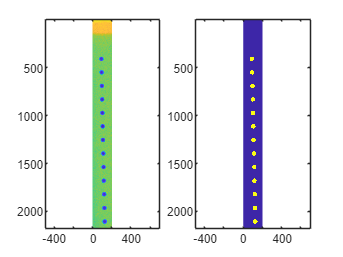

clc;clear;close;


load croppedImage.txt
load croppedImageBin.txt

figure;
subplot(1,2,1)
imagesc(croppedImage)
axis equal
subplot(1,2,2)
imagesc(croppedImageBin)
axis equal

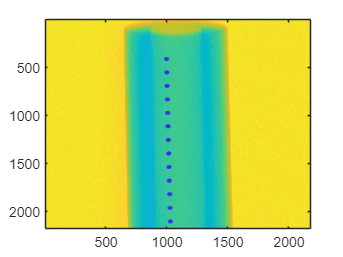


nchn = 2176;
nrow = 2176;
prep_file = "cut10.raw";
offsetskip = 0;
viewskip=0;
fid=fopen(prep_file);
fread(fid,offsetskip,'uint8');
for iv=1:viewskip
    fread(fid,nchn*nrow,'uint16');
end

for i = 1:10
    data(:,i) = fread(fid,nchn*nrow,'uint16');
end

data = reshape(data,nchn,nrow,[]);
data = permute(data,[2,1,3]);

for i = 1:10
    testdata(:,:,i) = rot90(data(:,:,i));
end
figure;
% imshow(testdata, []);  % 显示16位图像
imagesc(testdata(:,:,10));  % 显示16位图像

for i = 1:10
    temp = testdata(:,:,i);
    testdata_mean = mean(temp,"all");
    testdata_min = min(temp,[],"all");
    


    threshold = (testdata_mean - testdata_min) * 0.2;

    temp(temp > testdata_min + threshold) = 0;


    % databounds = struct();
    databounds(i,:) = calculateBounds(temp,2176,2176,200);
end

堆数据1的行列边界: 最小行 = 389, 最大行 = 428, 最小列 = 1016, 最大列 = 1053
堆数据1的中心: 行 = 4.085000e+02, 列 = 1.034500e+03
堆数据1的宽度和高度: 宽度 = 38, 高度 = 40

堆数据2的行列边界: 最小行 = 529, 最大行 = 568, 最小列 = 1016, 最大列 = 1056
堆数据2的中心: 行 = 5.485000e+02, 列 = 1036
堆数据2的宽度和高度: 宽度 = 41, 高度 = 40

堆数据3的行列边界: 最小行 = 670, 最大行 = 709, 最小列 = 1016, 最大列 = 1059
堆数据3的中心: 行 = 6.895000e+02, 列 = 1.037500e+03
堆数据3的宽度和高度: 宽度 = 44, 高度 = 40

堆数据4的行列边界: 最小行 = 811, 最大行 = 850, 最小列 = 1016, 最大列 = 1063
堆数据4的中心: 行 = 8.305000e+02, 列 = 1.039500e+03
堆数据4的宽度和高度: 宽度 = 48, 高度 = 40

堆数据5的行列边界: 最小行 = 952, 最大行 = 991, 最小列 = 1016, 最大列 = 1065
堆数据5的中心: 行 = 9.715000e+02, 列 = 1.040500e+03
堆数据5的宽度和高度: 宽度 = 50, 高度 = 40

堆数据6的行列边界: 最小行 = 1092, 最大行 = 1131, 最小列 = 1016, 最大列 = 1068
堆数据6的中心: 行 = 1.111500e+03, 列 = 1042
堆数据6的宽度和高度: 宽度 = 53, 高度 = 40

堆数据7的行列边界: 最小行 = 1234, 最大行 = 1273, 最小列 = 1016, 最大列 = 1071
堆数据7的中心: 行 = 1.253500e+03, 列 = 1.043500e+03
堆数据7的宽度和高度: 宽度 = 56, 高度 = 40

堆数据8的行列边界: 最小行 = 1376, 最大行 = 1414, 最小列 = 1016, 最大列 = 1074
堆数据8的中心: 行 = 1395, 列 = 1045
堆数据8的宽度和高度: 宽度 =

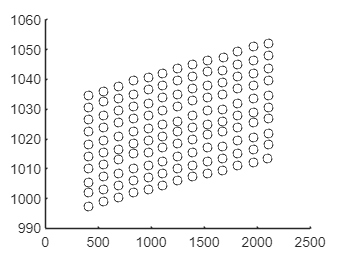


figure
hold on
for j = 1:13
    for i = 1:10
    scatter(databounds(i,j).centerRow,databounds(i,j).centerCol,'black');
    end
end
hold off

function dataBounds = calculateBounds(arr, nrow, nchn, expandCols)
% 创建一个空结构体数组
dataBounds = struct();

% 找到最大值的位置
[~, max_col] = find(arr == max(arr(:)), 1);  % 只返回第一个最大值的位置

% 在最大值列方向上扩充指定列数
minCol = max(1, max_col - expandCols);  % 防止列索引小于1
maxCol = min(nchn, max_col + expandCols);  % 防止列索引大于nchn

% 初始化数据堆的边界信息
boundsCount = 1;  % 计数器，用于存储多个堆的信息

rowSum_cur = 0;
arr_RowSum = sum(arr,2);

for row = 2:nrow
    if(arr_RowSum(row - 1 ) ~= 0 && row == 2 )
        heapMinRow(boundsCount) = row - 1 ;
        continue;
    end

    if(arr_RowSum(row) ~= 0 && arr_RowSum(row-1) == 0)
        heapMinRow(boundsCount) = row;
        continue;
    end

    if(arr_RowSum(row) == 0 && arr_RowSum(row-1) ~= 0)
        heapMaxRow(boundsCount) = row - 1;
        boundsCount = boundsCount + 1;
        continue;
    end

    if(arr_RowSum(row) ~= 0 && row == nrow)
        heapMaxRow(boundsCount) = row;
        boundsCount = boundsCount + 1;
        continue;
    end
end

boundsCount = 1;

heapMinColtemp = maxCol;
heapMaxColtemp = minCol;
for row = 1:nrow

    if(row < heapMinRow(boundsCount))
        continue;
    end
    if(row > heapMinRow(boundsCount) && row <= heapMaxRow(boundsCount))
        for col_st = minCol:maxCol
            if(arr(row,col_st) ~= 0)
                heapMinColtemp = min([col_st,heapMinColtemp]);
            end
        end
        for col_ed = maxCol:-1:minCol
            if(arr(row,col_ed) ~= 0)
                heapMaxColtemp = max([col_ed,heapMaxColtemp]);
            end
        end

        if(row == heapMaxRow(boundsCount))

            heapMinCol(boundsCount) = heapMinColtemp;
            heapMaxCol(boundsCount) = heapMaxColtemp;
            % 存储数据堆的边界
            dataBounds(boundsCount).minRow = heapMinRow(boundsCount);
            dataBounds(boundsCount).maxRow = heapMaxRow(boundsCount);
            dataBounds(boundsCount).minCol = heapMinCol(boundsCount);
            dataBounds(boundsCount).maxCol = heapMaxCol(boundsCount);

            % 计算数据堆的中心
            centerRow = (heapMinRow(boundsCount) + heapMaxRow(boundsCount)) / 2;
            centerCol = (heapMinCol(boundsCount) + heapMaxCol(boundsCount)) / 2;
            dataBounds(boundsCount).centerRow = centerRow;
            dataBounds(boundsCount).centerCol = centerCol;

            % 计算数据堆的宽度和高度
            width = heapMaxCol(boundsCount) - heapMinCol(boundsCount) + 1;
            height = heapMaxRow(boundsCount) - heapMinRow(boundsCount) + 1;
            dataBounds(boundsCount).width = width;
            dataBounds(boundsCount).height = height;
            if(boundsCount == length(heapMinRow))
                break
            end
            boundsCount = boundsCount +1;

        end
    end


end
% 更新计数器


% 显示所有堆的结果（可选）
for i = 1:length(dataBounds)
    fprintf('堆数据%d的行列边界: 最小行 = %d, 最大行 = %d, 最小列 = %d, 最大列 = %d\n', ...
        i, dataBounds(i).minRow, dataBounds(i).maxRow, dataBounds(i).minCol, dataBounds(i).maxCol);
    fprintf('堆数据%d的中心: 行 = %d, 列 = %d\n', i, dataBounds(i).centerRow, dataBounds(i).centerCol);
    fprintf('堆数据%d的宽度和高度: 宽度 = %d, 高度 = %d\n\n', i, dataBounds(i).width, dataBounds(i).height);
end
end



function findDataPilesBoundary(matrix)
% 获取矩阵的行列数
[rows, cols] = size(matrix);

% 初始化访问标记矩阵
visited = false(rows, cols);

% 四个方向的移动：上、下、左、右
directions = [-1, 0; 1, 0; 0, -1; 0, 1];

% 初始化数据堆计数
boundsCount = 1;

% 遍历整个矩阵
for i = 1:rows
    for j = 1:cols
        % 如果当前位置是非零且未访问过
        if matrix(i, j) ~= 0 && ~visited(i, j)
            % 初始化当前堆的边界
            minRow = i; maxRow = i; minCol = j; maxCol = j;

            % 调用 DFS 进行深度优先搜索
            [minRow, maxRow, minCol, maxCol] = dfs(i, j, matrix, visited, directions, minRow, maxRow, minCol, maxCol);

            % 输出当前数据堆的边界
            fprintf('数据堆 %d 的边界:\n', boundsCount);
            fprintf('  最小行 = %d, 最大行 = %d\n', minRow, maxRow);
            fprintf('  最小列 = %d, 最大列 = %d\n', minCol, maxCol);

            % 计算数据堆的中心
            centerRow = (minRow + maxRow) / 2;
            centerCol = (minCol + maxCol) / 2;
            fprintf('  中心位置: 行 = %.2f, 列 = %.2f\n', centerRow, centerCol);

            % 计算数据堆的宽度和高度
            width = maxCol - minCol + 1;
            height = maxRow - minRow + 1;
            fprintf('  宽度 = %d, 高度 = %d\n\n', width, height);

            boundsCount = boundsCount + 1;  % 增加数据堆计数
        end
    end
end
end

% 深度优先搜索（DFS）函数
function [minRow, maxRow, minCol, maxCol] = dfs(i, j, matrix, visited, directions, minRow, maxRow, minCol, maxCol)
% 标记当前元素为已访问
visited(i, j) = true;

% 更新数据堆的边界
minRow = min(minRow, i);
maxRow = max(maxRow, i);
minCol = min(minCol, j);
maxCol = max(maxCol, j);

% 遍历四个方向
for k = 1:size(directions, 1)
    newRow = i + directions(k, 1);
    newCol = j + directions(k, 2);

    % 检查新位置是否在矩阵内，并且未被访问且是非零元素
    if newRow > 0 && newRow <= size(matrix, 1) && newCol > 0 && newCol <= size(matrix, 2)
        if matrix(newRow, newCol) ~= 0 && ~visited(newRow, newCol)
            % 递归进行DFS
            [minRow, maxRow, minCol, maxCol] = dfs(newRow, newCol, matrix, visited, directions, minRow, maxRow, minCol, maxCol);
        end
    end
end
end




